clc; clear all; close all;


## 1

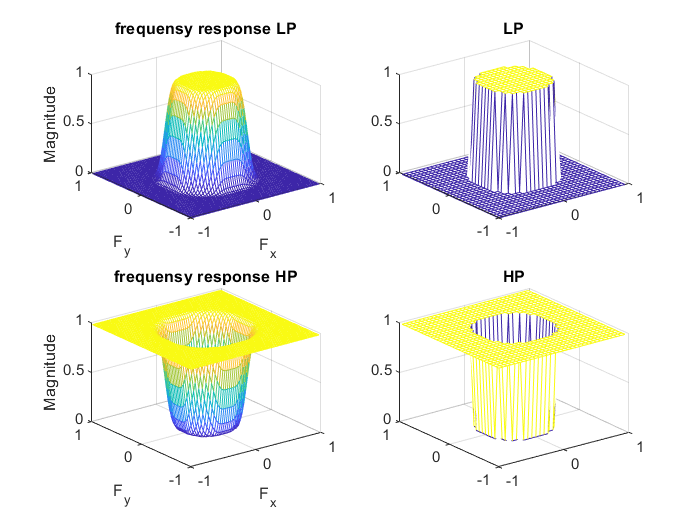

M = 32;
[f1,f2] = freqspace(M,'meshgrid'); %Create the frequency range vectors f1 and f2 using freqspace. len 32
r = sqrt(f1.^2 + f2.^2); %Compute the distance of each position from the center frequency.

%Create a matrix Hd that contains the desired freq response
Hhp = ones(M);
Hhp(r<0.5) = 0;
Hlp = zeros(M);
Hlp(r<0.5) = 1;

%Design the 1-D window
win = blackman(M);

hlp = fwind1(Hlp,win);
hhp = fwind1(Hhp,win);

figure
subplot(221)
freqz2(hlp);
title("frequensy response LP");
subplot(222)
mesh(f1,f2,Hlp);
title("LP");

subplot(223)
freqz2(hhp);
title("frequensy response HP");
subplot(224)
mesh(f1,f2,Hhp);
title("HP");

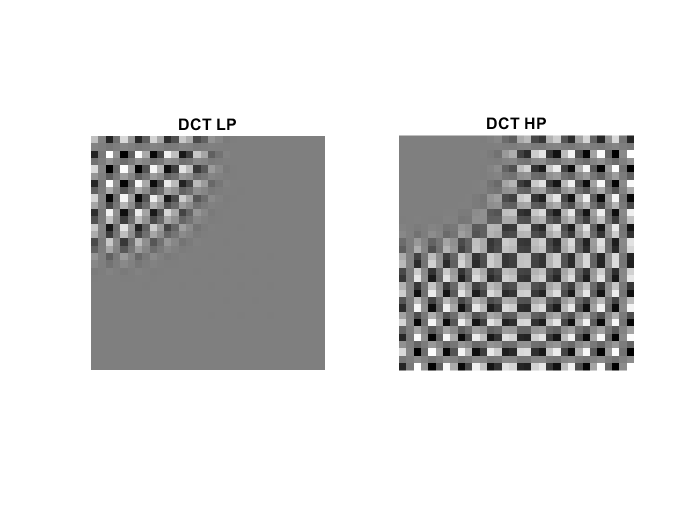


[x,cmap] = imread("lena512.png");
x = double(x);
DCTlp = dct2(hlp);
DCThp = dct2(hhp);

figure;
subplot(121)
imshow(DCTlp,cmap);
title("DCT LP");
subplot(122)
imshow(DCThp,cmap);
title("DCT HP");

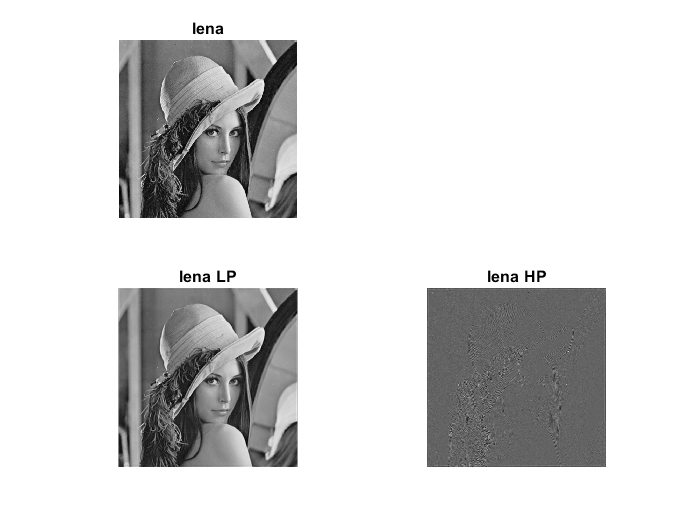


Yhp = filter2(hhp,x);
Ylp = filter2(hlp,x);




figure;
subplot(221)
imshow(x,cmap);
title("lena");
subplot(223)
imshow(Ylp, cmap);
title("lena LP");
subplot(224)
imshow(Yhp, cmap);
title("lena HP");

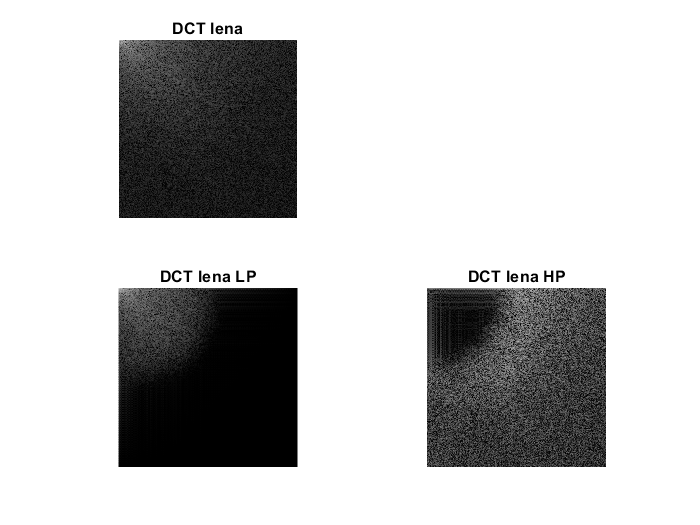


DCTx = dct2(x);
DCTYhp = dct2(Yhp);
DCTYlp = dct2(Ylp);

figure;
subplot(221)
imagesc
imshow(skaladB(DCTx),cmap);
title("DCT lena");
subplot(223)
imshow(skaladB(DCTYlp), cmap);
title("DCT lena LP");
subplot(224)
imshow(skaladB(DCTYhp), cmap);
title("DCT lena HP");

## 2

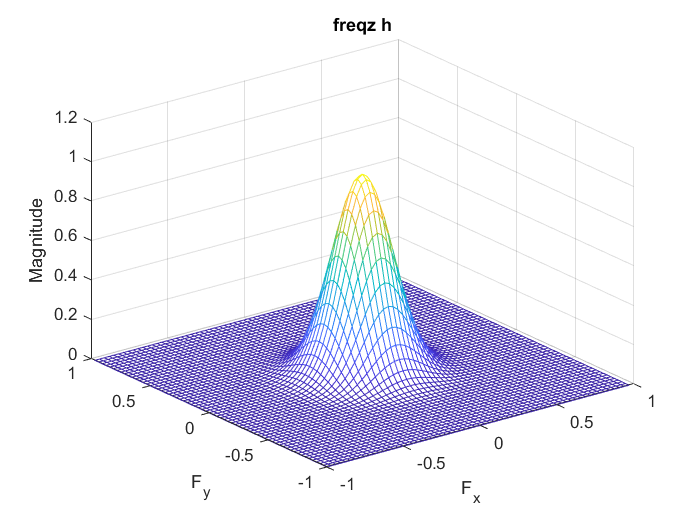

h = fspecial('gaussian',32,2);

filtered = filter2(h,x);
figure;
freqz2(h);
title("freqz h")

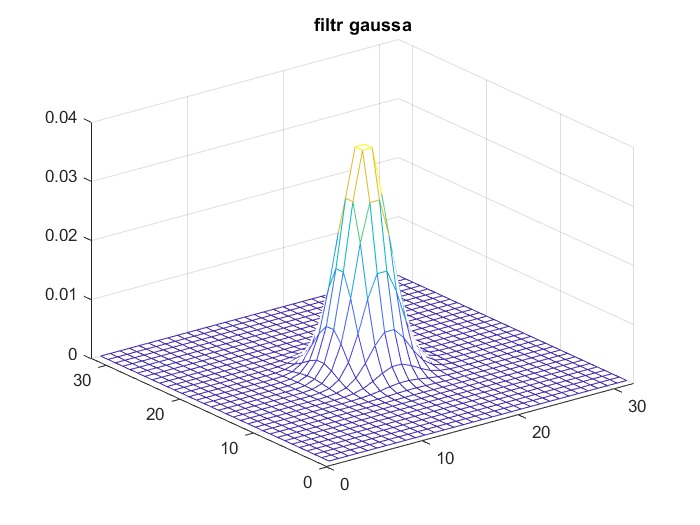

figure;
mesh(h);
title("filtr gaussa");

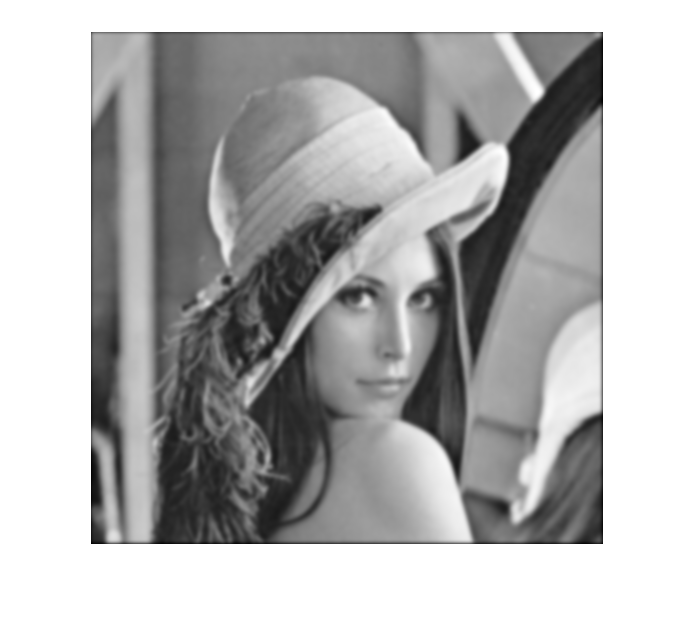

figure;
imshow(filtered,cmap);